## Visualizing Audio Quantization

Written by Dr. Steven Jacobs at the University of Pittsburgh for ECE 1560

### Load audio file


$$\Omega s=2\pi f_{s\;} =\frac{2\pi \;}{T_{s\;} }$$


%load audio signal
fileName = './Audio_Source/audio_sample.mp3';
[w, fs] = audioread(fileName);
w = w(:,1);
N_w = length(w) -1;

Ts = 1/fs; % sampling period

### Plot audio signal in time domain

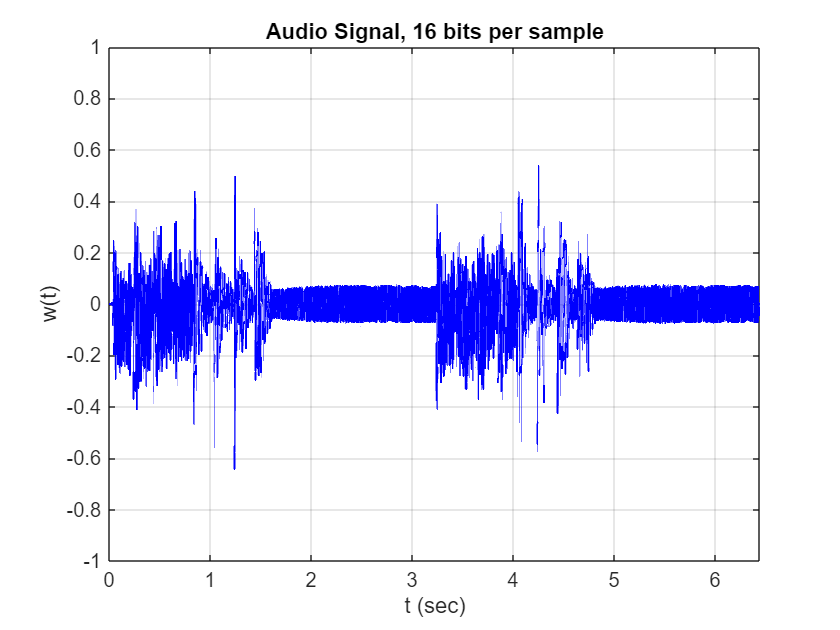

t = 0:Ts:Ts*N_w; % vector of time values
figure(1);
clf;
plot(t,w,'b','LineWidth',1);
axis([0 max(t) -1 1]);
grid on;
xlabel('t (sec)');
ylabel('w(t)');
title(['Audio Signal, 16 bits per sample']);

### Plot audio signal in frequency domain

- Vector of frequencies in Hz, ranges over $-f_s/2 \leq f < f_s/2$.  The frequency spacing is $f_s/N$.

- The fftshift function: shift zero-frequency component to the center of the spectrum. = Places negative frequencies on the left. used to visualize the fourier transform. 

f = (0:N_w) * (fs/N_w) - fs/2; % get vector of frequencies in Hz

W = Ts * fftshift(fft(w)); %compute discrete fourier transform coefficients
 
W_db = 20*log10(abs(W)); %compute the magnitude spectrum in dB units

figure(2);
clf;
plot(f/1000,W_db,'b','LineWidth',1);
xlim([min(f/1000), max(f/1000)]);
ylim([max(W_db)-60, max(W_db)]);
grid on;
xlabel('f (kHz)');
ylabel('|W(f)| in dB');

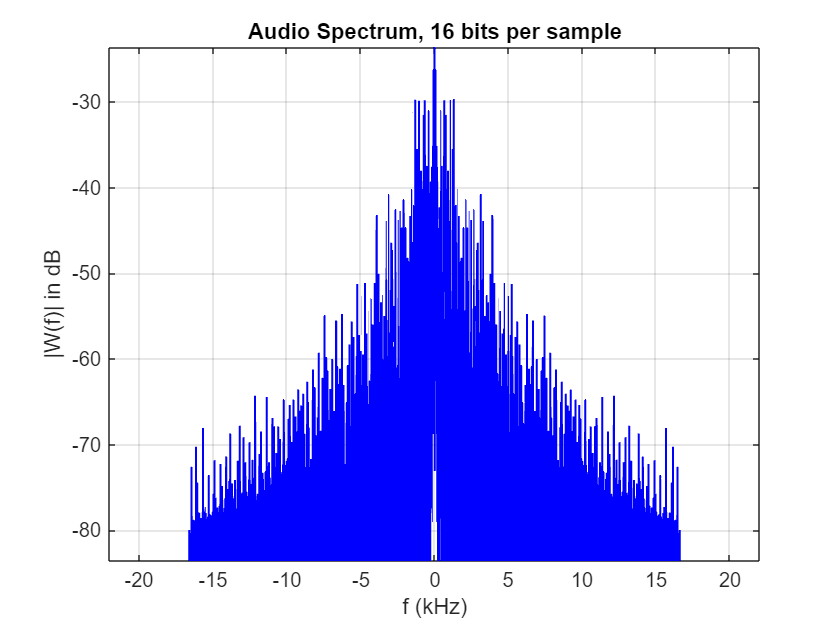

title('Audio Spectrum, 16 bits per sample');

### Perform Quantization and plot in time domain

using a mid-riser quantization scheme, which places the quantization levels in the center of each quantization bin.

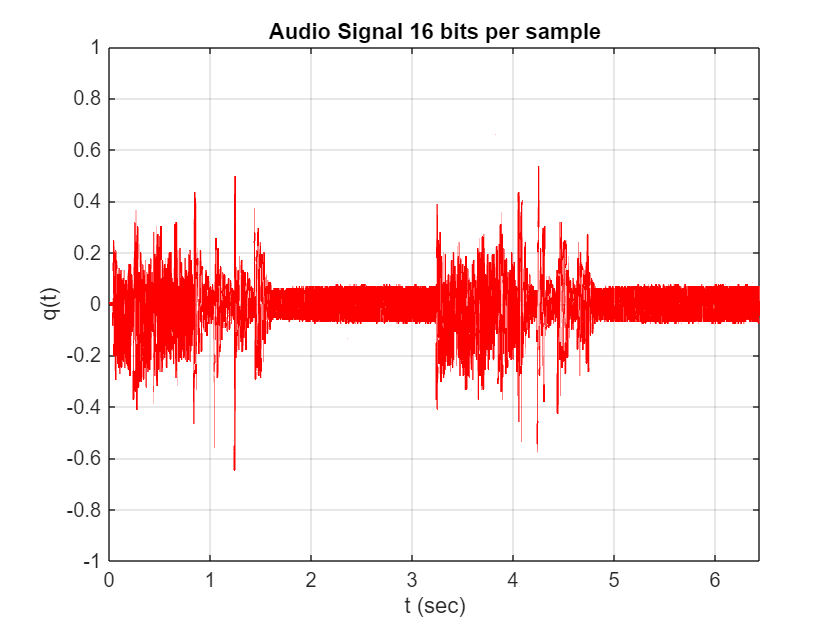

m = 16; % 16-bit quantization
M = m^2; % number of quantization levels
A = 1; % signal amplitude is A = 1 for all audio files
Delta = 2 * A / M; % quantizer step 

% minimum quantization level 
Q0 = -A + A/M;

% subtract Q0 from w(t) and divided by delta to obtain y(t)
y = (w - Q0) / Delta;

% round y(t) to the nearist integer to get k
k = round(y);
q = Q0 + k*Delta;

%plot quantized signal
figure(3);
clf;
plot(t,q,'r','LineWidth',1);
axis([0 max(t) -1 1]);
grid on;
xlabel('t (sec)');
ylabel('q(t)');
title('Audio Signal 16 bits per sample');

### Perform Quantization and plot in frequency domain

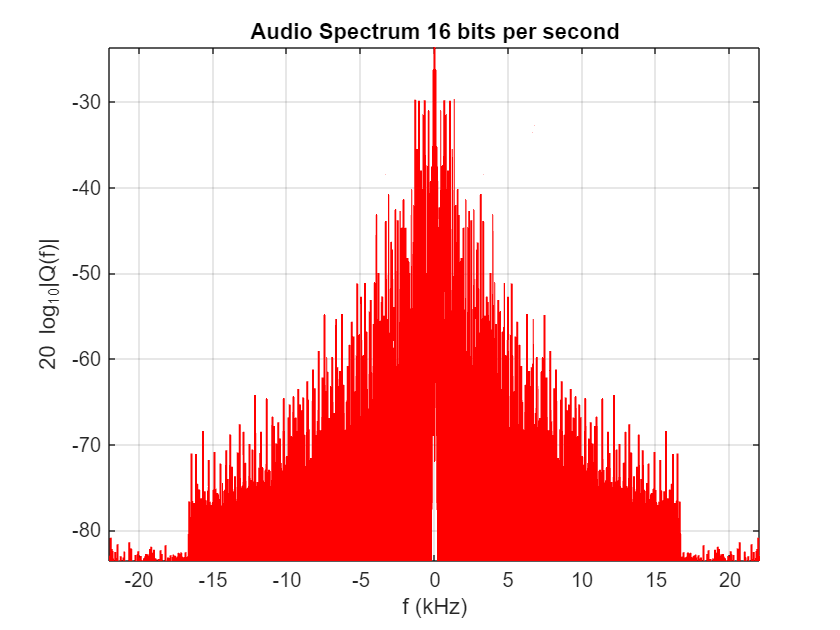

Q = Ts * fftshift(fft(q)); %compute discrete fourier transform coefficients
Q_db = 20*log10(abs(Q));

figure(4);
clf;
plot(f/1000,Q_db,'r','LineWidth',1);
xlim([min(f/1000), max(f/1000)]);
ylim([max(Q_db)-60, max(Q_db)]);
grid on;
xlabel('f (kHz)');
ylabel('20 log_{10}|Q(f)|');
title('Audio Spectrum 16 bits per second');